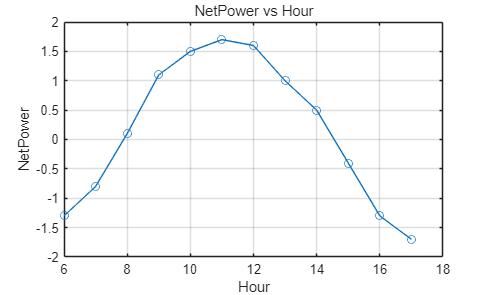

clear;
clc;

Hour = [6;7;8;9;10;11;12;13;14;15;16;17];
SolarGen = [0.5;1.2;2.4;3.8;4.6;5.1;5.4;5.0;4.2;3.0;1.7;0.8];
Demand = [1.8;2.0;2.3;2.7;3.1;3.4;3.8;4.0;3.7;3.4;3.0;2.5];
Battery = [3.2;3.0;3.1;3.8;4.5;5.2;5.9;6.3;6.5;6.1;5.4;4.7];

A = [Hour,SolarGen,Demand,Battery];
writematrix(A,'solar_system.txt');

B = load('solar_system.txt');
hour = B(:,1);
solar = B(:,2);
demand = B(:,3);
battery = B(:,4);
netPower = solar - demand;

figure
plot(hour,netPower,'-o')
xlabel('Hour')
ylabel('NetPower')
title('NetPower vs Hour')
grid on

clear;
clc;

D = [1 2.1 8 12;2 3.4 13 19;3 1.8 7 10;4 5.2 21 31;5 4.7 19 28;6 6.0 25 36;7 3.1 12 18;8 5.8 24 35];
writematrix(D,'drone_delivery.txt');
A = load('drone_delivery.txt');
DistanceKm = A(:,2)

DistanceKm =     2.1000
    3.4000
    1.8000
    5.2000
    4.7000
    6.0000
    3.1000
    5.8000


TimeMin = A(:,3)

TimeMin =      8
    13
     7
    21
    19
    25
    12
    24


BatteryUsed = A(:,4)

BatteryUsed =     12
    19
    10
    31
    28
    36
    18
    35


speed = DistanceKm ./ TimeMin

speed =     0.2625
    0.2615
    0.2571
    0.2476
    0.2474
    0.2400
    0.2583
    0.2417


BatteryPerKm = BatteryUsed ./ DistanceKm

BatteryPerKm =     5.7143
    5.5882
    5.5556
    5.9615
    5.9574
    6.0000
    5.8065
    6.0345


idx = find(BatteryPerKm > 6);
data = [A(idx,1),A(idx,2),BatteryPerKm(idx)]

data =     8.0000    5.8000    6.0345


clear;
clc;

Zone = ["Z1";"Z2";"Z3";"Z4";"Z5";"Z6";"Z7";"Z8"];
Temp = [22.5;24.1;21.8;25.3;23.7;26.0;22.9;24.8];
Humidity = [61;58;67;55;62;53;65;57];
Light = [420;460;390;520;480;550;410;500];
CO2 = [510;540;495;610;575;640;520;600];
Farm = table(Zone,Temp,Humidity,Light,CO2)

Farm = 8×5 table
    Zone    Temp    Humidity    Light    CO2
    ____    ____    ________    _____    ___

    "Z1"    22.5       61        420     510
    "Z2"    24.1       58        460     540
    "Z3"    21.8       67        390     495
    "Z4"    25.3       55        520     610
    "Z5"    23.7       62        480     575
    "Z6"      26       53        550     640
    "Z7"    22.9       65        410     520
    "Z8"    24.8       57        500     600


Farm.EnvIndex = 0.4*Farm.Temp + 0.01*Farm.Light +0.02*Farm.CO2;
Farm

Farm = 8×6 table
    Zone    Temp    Humidity    Light    CO2    EnvIndex
    ____    ____    ________    _____    ___    ________

    "Z1"    22.5       61        420     510      23.4  
    "Z2"    24.1       58        460     540     25.04  
    "Z3"    21.8       67        390     495     22.52  
    "Z4"    25.3       55        520     610     27.52  
    "Z5"    23.7       62        480     575     25.78  
    "Z6"      26       53        550     640      28.7  
    "Z7"    22.9       65        410     520     23.66  
    "Z8"    24.8       57        500     600     26.92  


HighEnv = Farm(Farm.EnvIndex>=25,:)

HighEnv = 5×6 table
    Zone    Temp    Humidity    Light    CO2    EnvIndex
    ____    ____    ________    _____    ___    ________

    "Z2"    24.1       58        460     540     25.04  
    "Z4"    25.3       55        520     610     27.52  
    "Z5"    23.7       62        480     575     25.78  
    "Z6"      26       53        550     640      28.7  
    "Z8"    24.8       57        500     600     26.92  


A = HighEnv(:,{'Zone','Temp','Light','EnvIndex'})

A = 5×4 table
    Zone    Temp    Light    EnvIndex
    ____    ____    _____    ________

    "Z2"    24.1     460      25.04  
    "Z4"    25.3     520      27.52  
    "Z5"    23.7     480      25.78  
    "Z6"      26     550       28.7  
    "Z8"    24.8     500      26.92  


clear;
clc;

Machine = ["M1";"M2";"M3";"M4";"M5";"M6";"M7";"M8";"M9";"M10"];
Vibration = [1.8;2.4;1.5;3.1;2.7;1.9;3.5;2.2;1.6;2.9];
Temp = [68;72;65;78;74;69;82;71;66;76];
Power = [4.5;5.1;4.2;6.3;5.7;4.8;6.8;5.0;4.4;6.0];
Defect = [2;5;1;8;6;3;10;4;1;7];

Factory = table(Machine,Vibration,Temp,Power,Defect)

Factory = 10×5 table
    Machine    Vibration    Temp    Power    Defect
    _______    _________    ____    _____    ______

     "M1"         1.8        68      4.5        2  
     "M2"         2.4        72      5.1        5  
     "M3"         1.5        65      4.2        1  
     "M4"         3.1        78      6.3        8  
     "M5"         2.7        74      5.7        6  
     "M6"         1.9        69      4.8        3  
     "M7"         3.5        82      6.8       10  
     "M8"         2.2        71        5        4  
     "M9"         1.6        66      4.4        1  
     "M10"        2.9        76        6        7  


Factory.RiskScore = Vibration.*Temp./Power;
Factory

Factory = 10×6 table
    Machine    Vibration    Temp    Power    Defect    RiskScore
    _______    _________    ____    _____    ______    _________

     "M1"         1.8        68      4.5        2         27.2  
     "M2"         2.4        72      5.1        5       33.882  
     "M3"         1.5        65      4.2        1       23.214  
     "M4"         3.1        78      6.3        8       38.381  
     "M5"         2.7        74      5.7        6       35.053  
     "M6"         1.9        69      4.8        3       27.312  
     "M7"         3.5        82      6.8       10       42.206  
     "M8"         2.2        71        5        4        31.24  
     "M9"         1.6        66      4.4        1           24  
     "M10"        2.9        76        6        7       36.733  


RiskMachines = Factory(Factory.RiskScore>=35 & Factory.Defect>=6,:);
A = RiskMachines(:,{'Machine','RiskScore','Defect'})

A = 4×3 table
    Machine    RiskScore    Defect
    _______    _________    ______

     "M4"       38.381         8  
     "M5"       35.053         6  
     "M7"       42.206        10  
     "M10"      36.733         7  



writetable(Factory,'factory_risk.csv')

clear;
clc;

url = ['https://archive.ics.uci.edu/ml/machine-learning-databases/abalone/abalone.data'];
Abalone = readtable(url,'FileType','text','ReadVariableNames',false);
Abalone.Properties.VariableNames = {'Sex','Length','Diameter','Height','WholeWeight','ShuckedWeight','VisceraWeight','ShellWeight','Rings'}

Abalone = 4177×9 table
     Sex     Length    Diameter    Height    WholeWeight    ShuckedWeight    VisceraWeight    ShellWeight    Rings
    _____    ______    ________    ______    ___________    _____________    _____________    ___________    _____

    {'M'}    0.455      0.365      0.095        0.514          0.2245            0.101            0.15        15  
    {'M'}     0.35      0.265       0.09       0.2255          0.0995           0.0485            0.07         7  
    {'F'}     0.53       0.42      0.135        0.677          0.2565           0.1415            0.21         9  
    {'M'}     0.44      0.365      0.125        0.516          0.2155            0.114           0.155        10  
    {'I'}     0.33      0.255       0.08        0.205          0.0895           0.0395           0.055         7  
    {'I'}    0.425        0.3      0.095       0.3515           0.141           0.0775            0.12         8  
    {'F'}     0.53      0.415       0.15       0.7775   

T2 = Abalone(:,{'WholeWeight','ShellWeight','Rings'})

T2 = 4177×3 table
    WholeWeight    ShellWeight    Rings
    ___________    ___________    _____

       0.514           0.15        15  
      0.2255           0.07         7  
       0.677           0.21         9  
       0.516          0.155        10  
       0.205          0.055         7  
      0.3515           0.12         8  
      0.7775           0.33        20  
       0.768           0.26        16  
      0.5095          0.165         9  
      0.8945           0.32        19  
      0.6065           0.21        14  
       0.406          0.135        10  
      0.5415           0.19        11  
      0.6845          0.205        10  
      0.4755          0.185        10  
      0.6645           0.24        12  


OldMale = Abalone(strcmp(Abalone.Sex,'M') & Abalone.Rings>=15,:);
A = OldMale(:,{'Sex','Length','WholeWeight','Rings'})

A = 167×4 table
     Sex     Length    WholeWeight    Rings
    _____    ______    ___________    _____

    {'M'}    0.455        0.514        15  
    {'M'}    0.605       0.9365        15  
    {'M'}    0.665        1.338        18  
    {'M'}    0.595       1.3175        21  
    {'M'}    0.565       0.8115        15  
    {'M'}    0.695        1.494        15  
    {'M'}     0.55        0.843        15  
    {'M'}     0.53        0.883        15  
    {'M'}      0.7       1.7255        19  
    {'M'}     0.71        1.959        18  
    {'M'}    0.595        1.262        17  
    {'M'}     0.65       1.3445        16  
    {'M'}     0.59        1.053        15  
    {'M'}    0.645        1.514        16  
    {'M'}     0.64        1.368        21  
    {'M'}     0.64       1.3035        16  


clear;
clc;

url = ['https://archive.ics.uci.edu/ml/machine-learning-databases/abalone/abalone.data'];
Abalone = readtable(url,'FileType','text','ReadVariableNames',false);
Abalone.Properties.VariableNames = {'Sex','Length','Diameter','Height','WholeWeight','ShuckedWeight','VisceraWeight','ShellWeight','Rings'}

Abalone = 4177×9 table
     Sex     Length    Diameter    Height    WholeWeight    ShuckedWeight    VisceraWeight    ShellWeight    Rings
    _____    ______    ________    ______    ___________    _____________    _____________    ___________    _____

    {'M'}    0.455      0.365      0.095        0.514          0.2245            0.101            0.15        15  
    {'M'}     0.35      0.265       0.09       0.2255          0.0995           0.0485            0.07         7  
    {'F'}     0.53       0.42      0.135        0.677          0.2565           0.1415            0.21         9  
    {'M'}     0.44      0.365      0.125        0.516          0.2155            0.114           0.155        10  
    {'I'}     0.33      0.255       0.08        0.205          0.0895           0.0395           0.055         7  
    {'I'}    0.425        0.3      0.095       0.3515           0.141           0.0775            0.12         8  
    {'F'}     0.53      0.415       0.15       0.7775   

Abalone.ShellRatio = Abalone.ShellWeight ./ Abalone.WholeWeight;
HardShell = Abalone(Abalone.ShellRatio>=0.25 & Abalone.Rings>=12,:);
A = HardShell(:,{'Sex','WholeWeight','ShellWeight','ShellRatio','Rings'})

A = 896×5 table
     Sex     WholeWeight    ShellWeight    ShellRatio    Rings
    _____    ___________    ___________    __________    _____

    {'M'}       0.514           0.15        0.29183       15  
    {'F'}      0.7775           0.33        0.42444       20  
    {'F'}       0.768           0.26        0.33854       16  
    {'F'}      0.8945           0.32        0.35774       19  
    {'F'}      0.6065           0.21        0.34625       14  
    {'M'}      0.6645           0.24        0.36117       12  
    {'F'}      0.9395           0.27        0.28739       12  
    {'M'}       0.931           0.28        0.30075       12  
    {'M'}      0.9365          0.295          0.315       15  
    {'F'}       1.639           0.46        0.28066       15  
    {'M'}       1.338           0.35        0.26158       18  
    {'F'}       1.798          0.455        0.25306       19  
    {'F'}      1.7095           0.49        0.28663       13  
    {'F'}       1.217           0.34  

ratioData = Abalone{:,'ShellRatio'}

ratioData =     0.2918
    0.3104
    0.3102
    0.3004
    0.2683
    0.3414
    0.4244
    0.3385
    0.3238
    0.3577
    0.3462
    0.3325
    0.3509
    0.2995
    0.3891


clear;
clc;

url = ['https://archive.ics.uci.edu/ml/machine-learning-databases/forest-fires/forestfires.csv'];
Fire = readtable(url);

temp = Fire.temp

temp =     8.2000
   18.0000
   14.6000
    8.3000
   11.4000
   22.2000
   24.1000
    8.0000
   13.1000
   22.8000
   17.8000
   19.3000
   17.0000
   21.3000
   26.4000


RH = Fire.RH

RH =     51
    33
    33
    97
    99
    29
    27
    86
    63
    40
    51
    38
    72
    42
    21


wind = Fire.wind

wind =     6.7000
    0.9000
    1.3000
    4.0000
    1.8000
    5.4000
    3.1000
    2.2000
    5.4000
    4.0000
    7.2000
    4.0000
    6.7000
    2.2000
    4.5000


rain = Fire.rain

rain =          0
         0
         0
    0.2000
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


area = Fire.area

area = 1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



HotDryFires = Fire(Fire.temp>=25 & Fire.RH<=35,:);
A = HotDryFires(:,{'month','day','temp','RH','wind','area'})

A = 54×6 table
     month       day      temp    RH    wind     area 
    _______    _______    ____    __    ____    ______

    {'sep'}    {'wed'}    26.4    21    4.5          0
    {'sep'}    {'sat'}    30.2    24    2.7          0
    {'sep'}    {'fri'}    25.4    24    3.6          0
    {'sep'}    {'wed'}    25.9    24      4          0
    {'sep'}    {'thu'}    27.7    24    2.2          0
    {'sep'}    {'fri'}    27.6    30    1.3          0
    {'sep'}    {'thu'}    25.4    27    2.2          0
    {'aug'}    {'thu'}    27.4    22      4        0.9
    {'sep'}    {'sat'}    29.6    27    2.7       1.46
    {'sep'}    {'sat'}    28.6    27    2.2       1.61
    {'sep'}    {'sun'}    28.3    26    3.1       64.1
    {'sep'}    {'wed'}    26.4    21    4.5      88.49
    {'sep'}    {'sun'}    27.8    27    3.1      95.18
    {'sep'}    {'sat'}    25.1    27      4     1090.8
    {'aug'}    {'wed'}    28.7    28    2.7          0
    {'aug'}    {'wed'}    26.8    25    3.1      

clear;
clc;

url = ['https://archive.ics.uci.edu/ml/machine-learning-databases/forest-fires/forestfires.csv'];
Fire = readtable(url);
Fire.RiskIndex = Fire.temp .* Fire.wind ./ Fire.RH;
RiskFire = Fire(Fire.RiskIndex>=2 & Fire.area > 0,:);
A = RiskFire(:,{'month','day','temp','RH','wind','area','RiskIndex'})

A = 105×7 table
     month       day      temp    RH    wind    area    RiskIndex
    _______    _______    ____    __    ____    ____    _________

    {'aug'}    {'wed'}    23.3    31    4.5     0.55     3.3823  
    {'aug'}    {'fri'}    21.2    51    8.9     0.61     3.6996  
    {'aug'}    {'wed'}    23.8    32    5.4     0.77     4.0163  
    {'aug'}    {'thu'}    27.4    22      4      0.9     4.9818  
    {'sep'}    {'tue'}    24.2    28    3.6     0.96     3.1114  
    {'aug'}    {'tue'}    17.4    43    6.7     1.07     2.7112  
    {'sep'}    {'thu'}    23.7    25    4.5     1.12      4.266  
    {'jun'}    {'fri'}    23.2    39    5.4     1.19     3.2123  
    {'sep'}    {'fri'}    20.1    47    4.9     1.46     2.0955  
    {'sep'}    {'sat'}    29.6    27    2.7     1.46       2.96  
    {'sep'}    {'sat'}    28.6    27    2.2     1.61     2.3304  
    {'aug'}    {'wed'}    20.5    35      4     1.64     2.3429  
    {'sep'}    {'fri'}      19    34    5.8     1.69     3.

writetable(A,'forest_risk.csv');

clear;
clc;

P = readtable('Penguindata.csv');

P.Properties.VariableNames

ans = 1×19 cell 배열
    {'studyName'}    {'SampleNumber'}    {'Species'}    {'Region'}    {'Latitude'}    {'Longitude'}    {'Island'}    {'Stage'}    {'IndividualID'}    {'ClutchCompletion'}    {'DateEgg'}    {'CulmenLength_mm_'}    {'CulmenDepth_mm_'}    {'FlipperLength_mm_'}    {'BodyMass_g_'}    {'Sex'}    {'Delta15N_o_oo_'}    {'Delta13C_o_oo_'}    {'Comments'}


A = P(P.BodyMass_g_>=4500,:)

A = 118×19 table
     studyName     SampleNumber                       Species                         Region      Latitude    Longitude       Island                Stage             IndividualID    ClutchCompletion     DateEgg      CulmenLength_mm_    CulmenDepth_mm_    FlipperLength_mm_    BodyMass_g_       Sex        Delta15N_o_oo_    Delta13C_o_oo_                                    Comments                                
    ___________    ____________    _____________________________________________    __________    ________    _________    _____________    ______________________    ____________    ________________    __________    ________________    _______________    _________________    ___________    __________    ______________    ______________    ________________________________________________________________________

    {'PAL0708'}          8         {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Anvers'}    -64.767      -64.083     {'Torgersen'}    {'Adult, 1 Egg

B = A(:,{'Species','Island','BodyMass_g_','Sex'})

B = 118×4 table
                       Species                          Island        BodyMass_g_       Sex    
    _____________________________________________    _____________    ___________    __________

    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4675        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4500        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4650        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4600        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4700        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4725        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4775        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4600        {'MALE'  }
    {'Chinstrap penguin

LargeGentoo = P(contains(P.Species,'Gentoo') & P.BodyMass_g_>= 5000,:)

LargeGentoo = 67×19 table
     studyName     SampleNumber                   Species                     Region      Latitude    Longitude      Island              Stage             IndividualID    ClutchCompletion     DateEgg      CulmenLength_mm_    CulmenDepth_mm_    FlipperLength_mm_    BodyMass_g_       Sex        Delta15N_o_oo_    Delta13C_o_oo_                    Comments                 
    ___________    ____________    _____________________________________    __________    ________    _________    __________    ______________________    ____________    ________________    __________    ________________    _______________    _________________    ___________    __________    ______________    ______________    _________________________________________

    {'PAL0708'}          2         {'Gentoo penguin (Pygoscelis papua)'}    {'Anvers'}     -64.8       -63.833     {'Biscoe'}    {'Adult, 1 Egg Stage'}     {'N31A2'}          {'Yes'}         11/27/0007            50              

clear;
clc;

P = readtable('Penguindata.csv');

P.BillRatio = P.CulmenLength_mm_ ./ P.CulmenDepth_mm_;
LongBill = P(P.BillRatio>=2.8,:);
A = LongBill(:,{'Species','CulmenLength_mm_','CulmenDepth_mm_','BillRatio'})

A = 131×4 table
                       Species                       CulmenLength_mm_    CulmenDepth_mm_    BillRatio
    _____________________________________________    ________________    _______________    _________

    {'Chinstrap penguin (Pygoscelis antarctica)'}          51.3               18.2           2.8187  
    {'Chinstrap penguin (Pygoscelis antarctica)'}            52               18.1           2.8729  
    {'Chinstrap penguin (Pygoscelis antarctica)'}            58               17.8           3.2584  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          47.5               16.8           2.8274  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          46.9               16.6           2.8253  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          50.9               17.9           2.8436  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          49.8               17.3           2.8786  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          48.1  

billRatioData = P{:,'BillRatio'};

clear;
clc;

H = readtable('heart_failure.csv');
H.Properties.VariableNames

ans = 1×13 cell 배열
    {'age'}    {'anaemia'}    {'creatinine_phosphokinase'}    {'diabetes'}    {'ejection_fraction'}    {'high_blood_pressure'}    {'platelets'}    {'serum_creatinine'}    {'serum_sodium'}    {'sex'}    {'smoking'}    {'time'}    {'DEATH_EVENT'}


HighRisk = H(H.age>=70 & H.ejection_fraction<=35,:);
A = HighRisk(:,{'age','ejection_fraction','serum_creatinine','serum_sodium','DEATH_EVENT'})

A = 31×5 table
    age    ejection_fraction    serum_creatinine    serum_sodium    DEATH_EVENT
    ___    _________________    ________________    ____________    ___________

    75            20                   1.9              130              1     
    75            15                   1.2              137              1     
    80            35                   9.4              133              1     
    70            25                     1              140              1     
    75            30                  1.83              134              1     
    82            30                   1.2              132              1     
    70            20                  1.83              134              1     
    80            20                   4.4              133              1     
    95            30                     2              132              1     
    70            35                   2.7              138              0     
    72            20    

DeathGroup = H(H.DEATH_EVENT==1,:)

DeathGroup = 96×13 table
    age    anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ___    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

    75        0                  582                 0               20                     1               2.65e+05          1.9               130          1        0         4          1     
    55        0                 7861                 0               38                     0             2.6336e+05          1.1               136          1        0         6          1     
    65        0                  146                 0               20                     0               1.62e+05          1.3               129          1        1         7          1     
    

SurvivalGroup = H(H.DEATH_EVENT==0,:)

SurvivalGroup = 203×13 table
    age    anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ___    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

    49        1                   80                 0               30                     1               4.27e+05             1              138          0        0        12          0     
    65        1                   52                 0               25                     1               2.76e+05           1.3              137          0        0        16          0     
    53        0                   63                 1               60                     0               3.68e+05           0.8              135          1        0        22          0     


clear;
clc;

H = readtable('heart_failure.csv');

H.RiskScore = H.age ./ H.ejection_fraction + H.serum_creatinine;
RiskScoreGroup = H(H.RiskScore>=4,:);
A = RiskScoreGroup(:,{'age','ejection_fraction','serum_creatinine','RiskScore','DEATH_EVENT'})

A = 59×5 table
    age    ejection_fraction    serum_creatinine    RiskScore    DEATH_EVENT
    ___    _________________    ________________    _________    ___________

    75            20                   1.9             5.65           1     
    65            20                   1.3             4.55           1     
    50            20                   1.9              4.4           1     
    65            20                   2.7             5.95           1     
    90            40                   2.1             4.35           1     
    75            15                   1.2              6.2           1     
    80            35                   9.4           11.686           1     
    75            38                     4           5.9737           1     
    45            14                   0.8           4.0143           1     
    75            30                  1.83             4.33           1     
    80            38                   1.9           4.0053 

writetable(A,'heart_risk_group.csv')

clear;
clc;

B = readtable("bank-full.csv");
B.Properties.VariableNames

ans = 1×17 cell 배열
    {'age'}    {'job'}    {'marital'}    {'education'}    {'default'}    {'balance'}    {'housing'}    {'loan'}    {'contact'}    {'day'}    {'month'}    {'duration'}    {'campaign'}    {'pdays'}    {'previous'}    {'poutcome'}    {'y'}


age = B.age;
balance = B.balance;
loan = B.loan;
y = B.y;
T1 = B(B.age>=40 & B.balance>=2000 & strcmp(B.loan,'no'),:)

T1 = 4329×17 table
    age          job            marital         education      default    balance    housing     loan       contact      day     month     duration    campaign    pdays    previous     poutcome         y   
    ___    _______________    ____________    _____________    _______    _______    _______    ______    ___________    ___    _______    ________    ________    _____    ________    ___________    _______

    58     {'management' }    {'married' }    {'tertiary' }    {'no'}       2143     {'yes'}    {'no'}    {'unknown'}     5     {'may'}       261         1         -1         0        {'unknown'}    {'no' }
    51     {'management' }    {'married' }    {'tertiary' }    {'no'}      10635     {'yes'}    {'no'}    {'unknown'}     5     {'may'}       336         1         -1         0        {'unknown'}    {'no' }
    44     {'services'   }    {'divorced'}    {'secondary'}    {'no'}       2586     {'yes'}    {'no'}    {'unknown'}     5     {'may'}       160       

T2 = T1(:,{'age','balance','y'})

T2 = 4329×3 table
    age    balance       y   
    ___    _______    _______

    58       2143     {'no' }
    51      10635     {'no' }
    44       2586     {'no' }
    51       6530     {'no' }
    59       2343     {'yes'}
    55       2476     {'yes'}
    40       4384     {'no' }
    54       4080     {'no' }
    51       2127     {'no' }
    50       5699     {'no' }
    49       3237     {'no' }
    51       2248     {'no' }
    45      24598     {'no' }
    40       8486     {'no' }
    54       2102     {'no' }
    55       5345     {'no' }


T2.NewFlag = strcmp(T2.y,'yes')

T2 = 4329×4 table
    age    balance       y       NewFlag
    ___    _______    _______    _______

    58       2143     {'no' }     false 
    51      10635     {'no' }     false 
    44       2586     {'no' }     false 
    51       6530     {'no' }     false 
    59       2343     {'yes'}     true  
    55       2476     {'yes'}     true  
    40       4384     {'no' }     false 
    54       4080     {'no' }     false 
    51       2127     {'no' }     false 
    50       5699     {'no' }     false 
    49       3237     {'no' }     false 
    51       2248     {'no' }     false 
    45      24598     {'no' }     false 
    40       8486     {'no' }     false 
    54       2102     {'no' }     false 
    55       5345     {'no' }     false 


Subscribed = T2(T2.NewFlag==1,:)

Subscribed = 758×4 table
    age    balance       y       NewFlag
    ___    _______    _______    _______

    59      2343      {'yes'}     true  
    55      2476      {'yes'}     true  
    43      2067      {'yes'}     true  
    52      2240      {'yes'}     true  
    43      3285      {'yes'}     true  
    52      3923      {'yes'}     true  
    41      2823      {'yes'}     true  
    40      3652      {'yes'}     true  
    51      7180      {'yes'}     true  
    41      5291      {'yes'}     true  
    43      3173      {'yes'}     true  
    44      4580      {'yes'}     true  
    41      2453      {'yes'}     true  
    54      4393      {'yes'}     true  
    44      5773      {'yes'}     true  
    45      3354      {'yes'}     true  


balanceVec = Subscribed{:,'balance'};
avgBalance = mean(balanceVec);

writetable(Subscribed,'bank_selected.csv')